# standardize card image

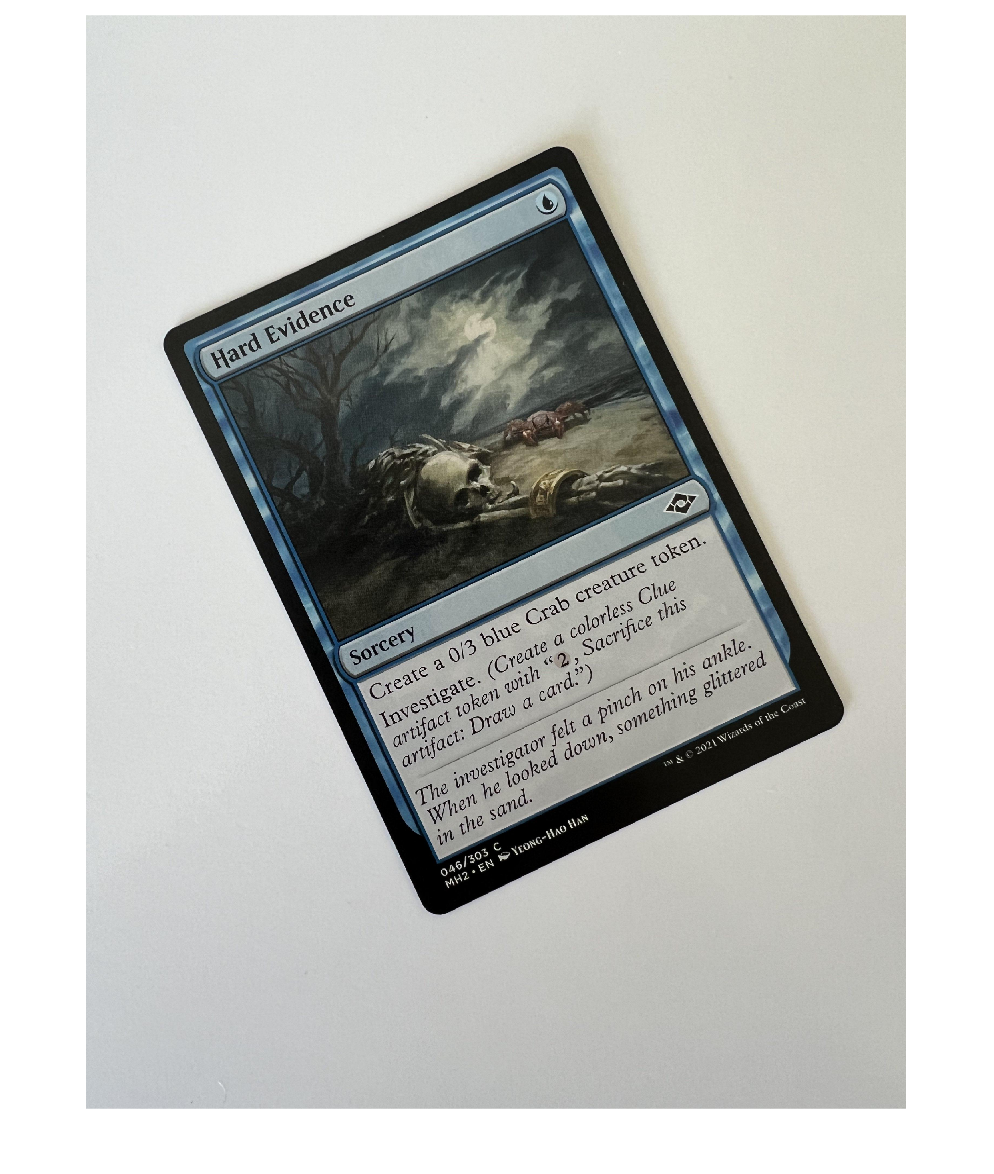

realImg = imread("hard_evidecne_rotated.jpg");
ogImg = realImg;
figure;
imshow(realImg);

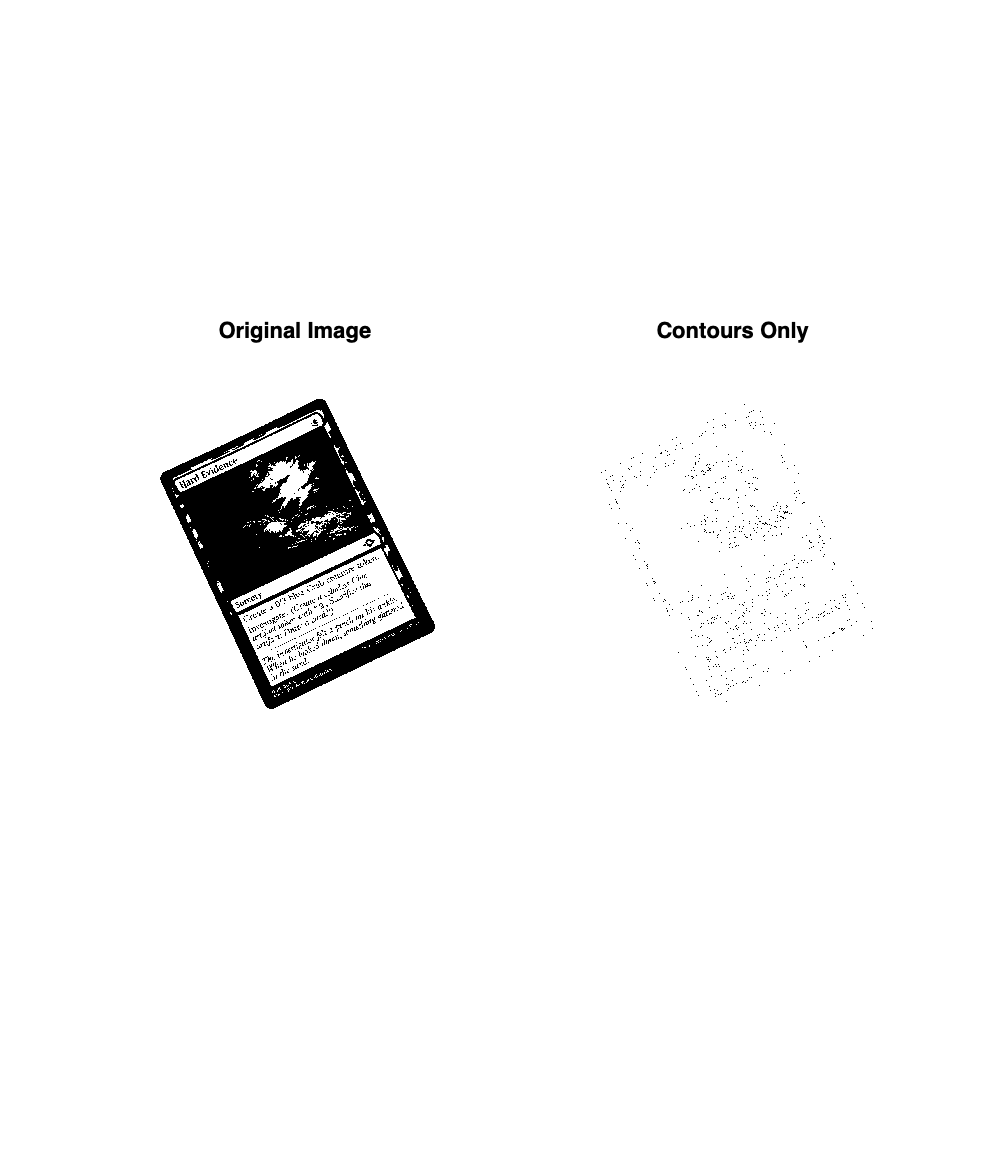


realImg = rgb2gray(realImg);
realImg = imbinarize(realImg,graythresh(realImg));

% % Apply edge detection to obtain binary edges
% edges = edge(realImg, 'Canny'); % You can choose other edge detection methods as well
% 
% % Multiply the binary edge map with the original image to extract only the contour pixels
% contourImage = realImg;
% contourImage(repmat(~edges, [1, 1, size(realImg, 3)])) = 1; % Set non-edge pixels to zero
% 
% % Display the original image and the contour image side by side
% subplot(1,2,1);
% imshow(realImg);
% title('Original Image');
% subplot(1,2,2);
% imshow(contourImage);
% title('Contours Only');

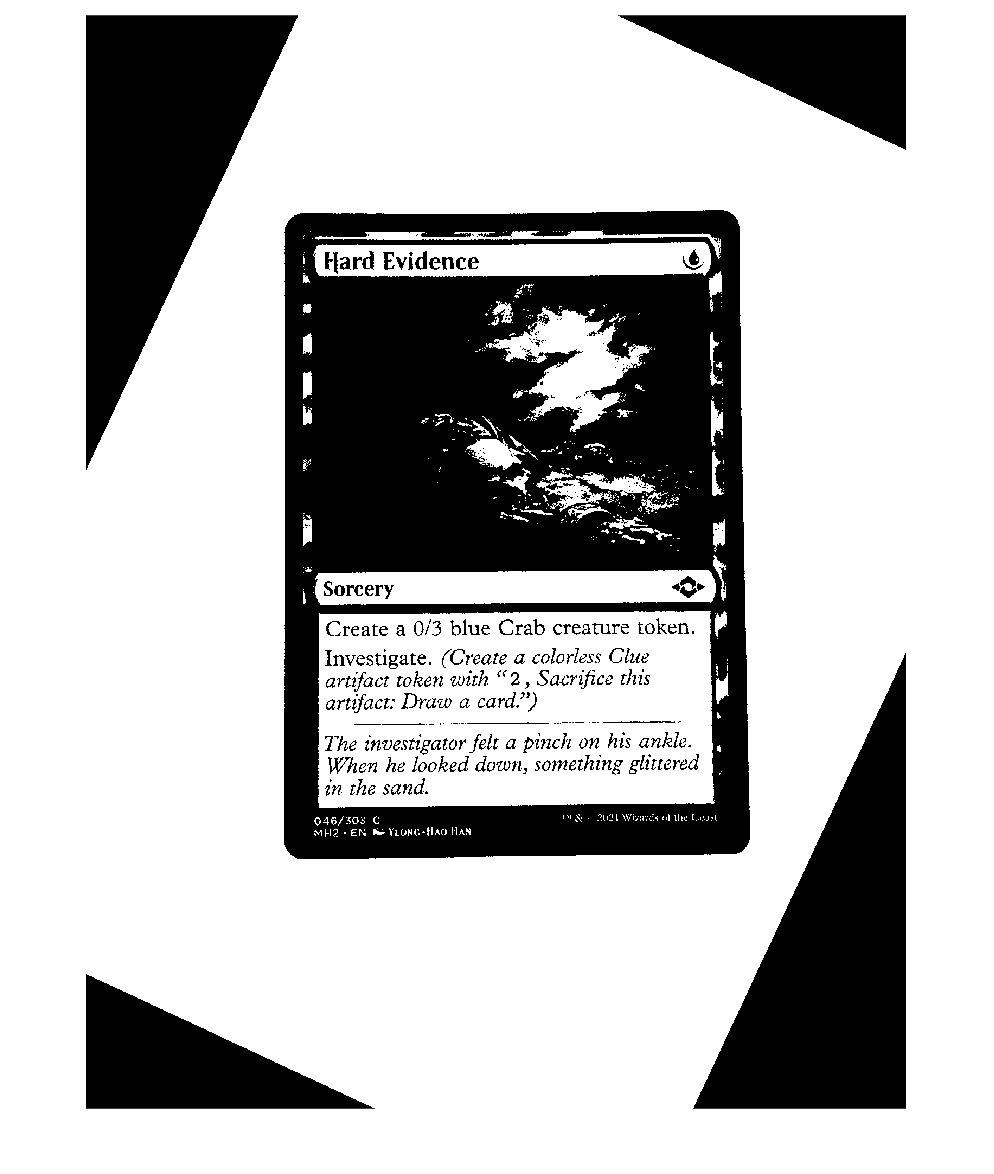



% % Obtain the boundary coordinates using bwboundaries function
% boundaries = bwboundaries(edges);
% 
% % Display the original image
% imshow(realImg);
% hold on;
% 
% % Plot the contour points on top of the original image
% for k = 1:length(boundaries)
%     boundary = boundaries{k};
%     
%     plot(boundary(:, 2), boundary(:, 1), 'r', 'LineWidth', 2); 
% end


[h,l,t] = hough(edge(realImg,"sobel"));
peaks = houghpeaks(h,1);
lines = houghlines(edge(realImg,"sobel"),l,t,peaks);

angle = atan2(lines(1).point2(2)-lines(1).point1(2),lines(1).point2(1)-lines(1).point1(1));
corrected = imrotate(realImg,rad2deg(angle)-90,'bilinear','crop');

figure;
imshow(corrected);

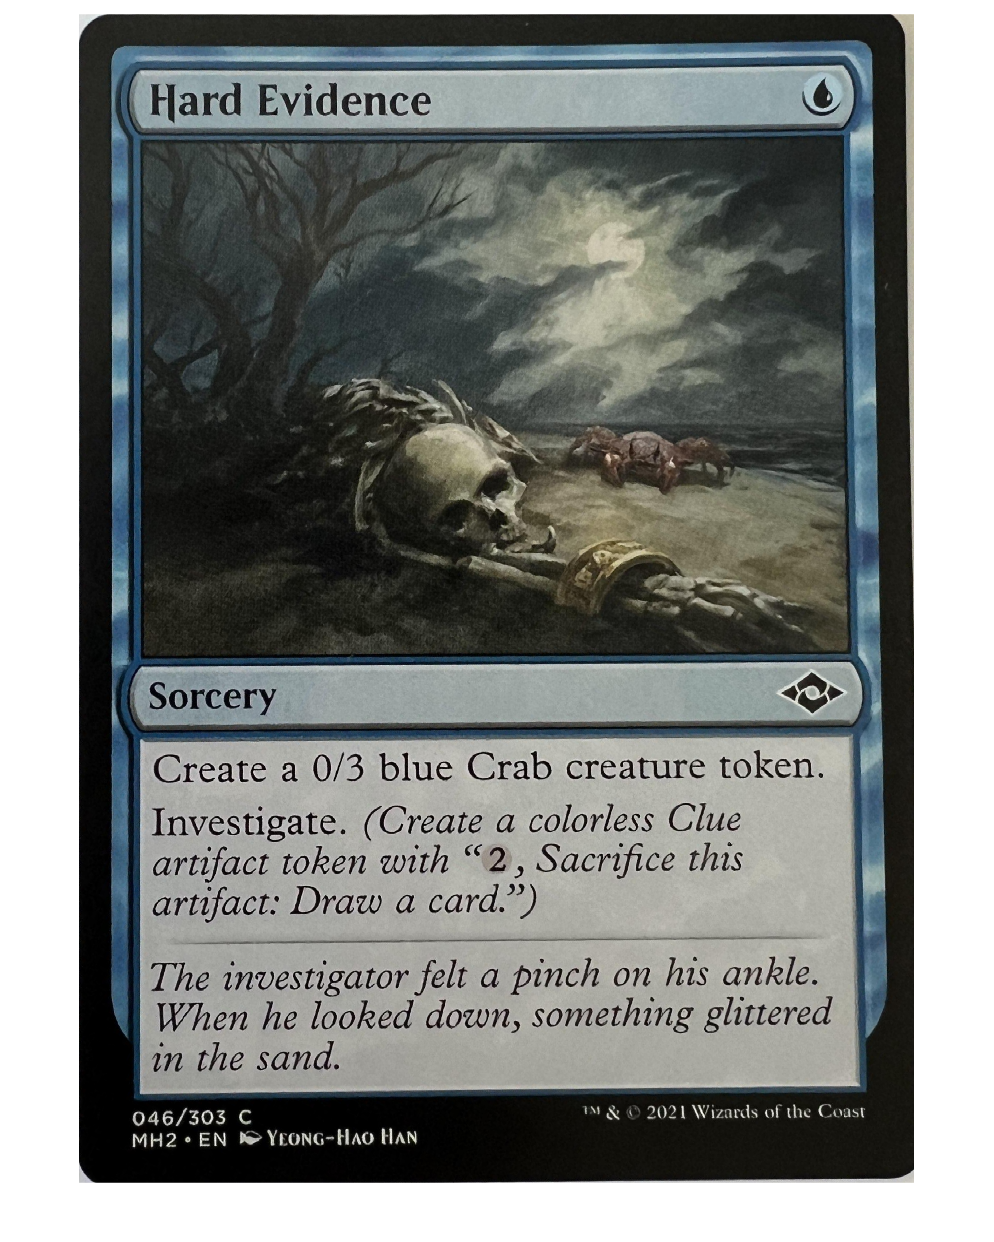

1 Sorcery

v
i
B“
l

E»; Cre a /3 blu Cra caé 
Q Investigate. (Create a colorless Clue

artifact token with “2 , Sacriﬁce this
artifact: Draw a card.’’)

The investigator felt a pinch on his ankle.
When he looked down, something glitte-red

in the sand.

046/303 C "‘ & ~ 202l\\"iznrdsnf1hc Com!‘
MH2 - EN v’o‘«Yr:0Nc.—llAo HAN

L '





[r,c] = size(corrected);


northmost = r;
southmost = 1;
westmost = c;
eastmost = 1;

for i=r/2-1:r/2+1
    for j=1:c
        if corrected(i,j) == 0
            if j < westmost
                westmost = j;
            end
            if j > eastmost
                eastmost = j;
            end
        end
    end
end

for i=r/2-1:r/2+1
    for j=c:1
        if corrected(i,j) == 0
            if j < eastmost
                eastmost = j;
            end
        end
    end
end

for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i < northmost
                northmost = i;
             
            end
        end
    end
end


for i=1:r
    for j=c/2-1:c/2+1
        if corrected(i,j) == 0
            if i > southmost
                southmost = i;
               
            end
        end
    end
end

cropRect = [westmost northmost (eastmost - westmost) (southmost - northmost)];
ogImg = imrotate(ogImg,rad2deg(angle)-90,'bilinear','crop');
croppedImg = imcrop(ogImg,cropRect);
figure;
imshow(croppedImg);



% get
test = imread("https://cards.scryfall.io/art_crop/front/1/4/1465ca9e-a997-4b8c-9677-6c7961f67eba.jpg?1562628773");

% queries
% color
% text

## Generate Scryfall Query

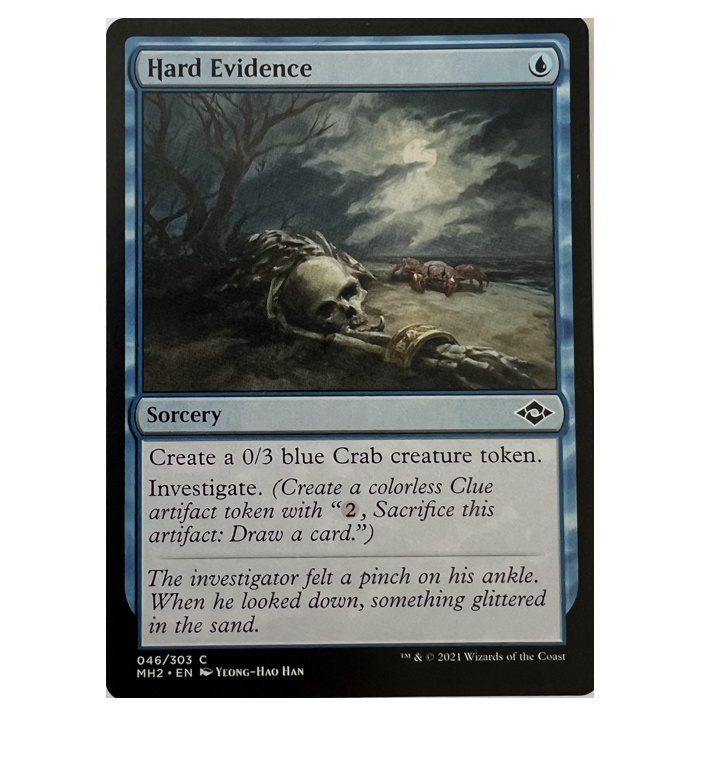


card = croppedImg;
normalSize = [680 488];
card = imresize(card, normalSize);
imshow(card);


% OCR test
 text = ocr(croppedImg);
 disp(text.Text);

1 Sorcery

v
i
B“
l

E»; Cre a /3 blu Cra caé 
Q Investigate. (Create a colorless Clue

artifact token with “2 , Sacriﬁce this
artifact: Draw a card.’’)

The investigator felt a pinch on his ankle.
When he looked down, something glitte-red

in the sand.

046/303 C "‘ & ~ 202l\\"iznrdsnf1hc Com!‘
MH2 - EN v’o‘«Yr:0Nc.—llAo HAN

L '




%croppedText = imcrop(croppedImg);
text = ocr(croppedText);
disp(text.Text);

046/303 c
MH2 - EN !9Y£oNc—HAo HAN




disp(text.Words(1));

    {'046/303'}



disp(text.Words(3));

    {'MH2'}



figure;
%croppedName = imcrop(croppedImg);
text = ocr(croppedName);
disp(text.Text);

K Hard Evidence





query = sprintf('https://api.scryfall.com/cards/%s/46',text.Words(3));

Error using sprintf
Function is not defined for 'cell' inputs.

% query = ['https://api.scryfall.com/cards/', text.Words(3), '/46'];
% query = join(query);

resultObj = webread(query);
result = imread(resultObj.image_uris.normal);
imshow(result);